# Create Trained Models for the 3 Algorithms

Sam Coleman and Rishita Sarin

%load data
load("trainFeatures.mat");
train_labels = emg.epochlabelscat';

## Algorithm 1

Average Amplitude Change (AAC) and Mean of Absolute Value (abs_mean). Only channels 1 and 2

features1 = [emg_aac(1:2, :); emg_abs_mean(1:2, :)]';
trainedAlg1 = fitcecoc(features1, train_labels);
% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart1 = cvpartition(train_labels,'KFold',kval); % k-fold stratified cross validation
partitionedModel1 = crossval(trainedAlg1,'CVPartition',cpart1);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions1, validationScores1] = kfoldPredict(partitionedModel1);
     
% Cross validation output
validationAccuracy1 = sum(validationPredictions1==train_labels)./length(train_labels);

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy1*100);


Validation accuracy = 72.92%


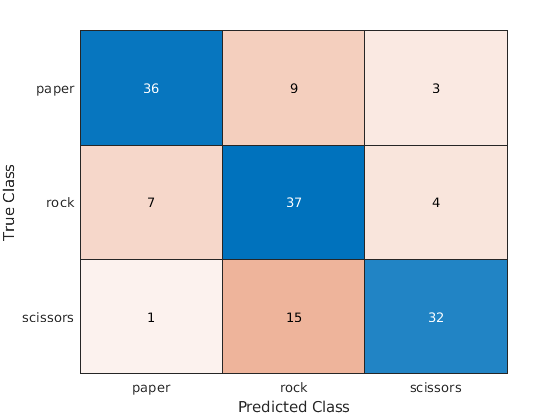

confusion_mat1 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties



confusion_mat1 = confusionchart(train_labels, validationPredictions1)

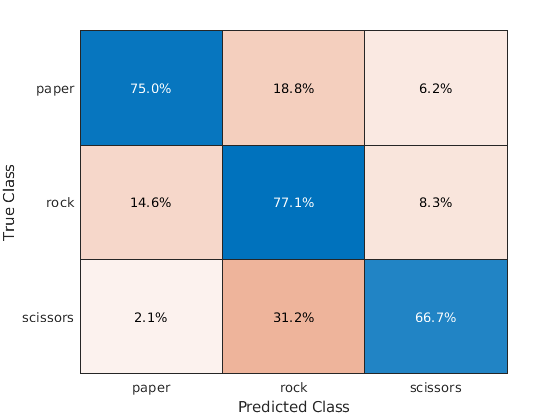

confusion_mat_norm1 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties


confusion_mat_norm1 = confusionchart(train_labels, validationPredictions1, 'Normalization','row-normalized')

## Algorithm 2

Root mean square (RMS). Only channels 1 and 2

features2 = [emg_rms(1:2, :)]';
trainedAlg2 = fitcecoc(features2, train_labels);
% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart2 = cvpartition(train_labels,'KFold',kval); % k-fold stratified cross validation
partitionedModel2 = crossval(trainedAlg2,'CVPartition',cpart2);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions2, validationScores2] = kfoldPredict(partitionedModel2);
     
% Cross validation output
validationAccuracy2 = sum(validationPredictions2==train_labels)./length(train_labels);

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy2*100);


Validation accuracy = 73.61%


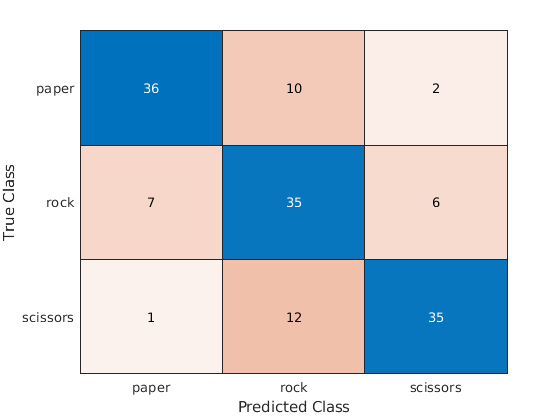

confusion_mat2 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties



confusion_mat2 = confusionchart(train_labels, validationPredictions2)

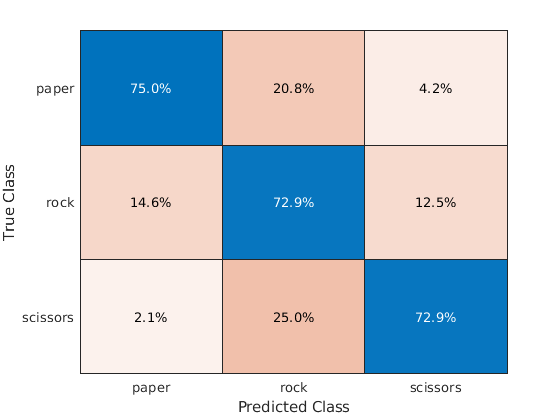

confusion_mat_norm2 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties


confusion_mat_norm2 = confusionchart(train_labels, validationPredictions2, 'Normalization','row-normalized')

## Algorithm 3

Average Amplitude Change (AAC), Mean of Absolute Value (abs_mean), Kurtosis (kurt), and Mean. Only channels 1 and 2

features3 = [emg_aac(1:2, :); emg_abs_mean(1:2, :); emg_kurt(1:2, :); emg_mean(1:2, :)]';
trainedAlg3 = fitcecoc(features3, train_labels);
% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart3 = cvpartition(train_labels,'KFold',kval); % k-fold stratified cross validation
partitionedModel3 = crossval(trainedAlg3,'CVPartition',cpart3);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions3, validationScores3] = kfoldPredict(partitionedModel3);
     
% Cross validation output
validationAccuracy3 = sum(validationPredictions3==train_labels)./length(train_labels);

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy3*100);


Validation accuracy = 72.22%


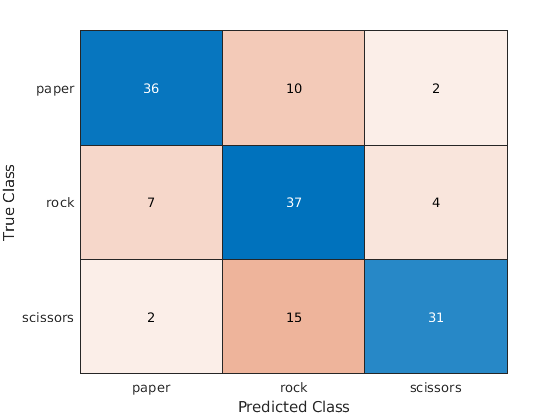

confusion_mat3 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties



confusion_mat3 = confusionchart(train_labels, validationPredictions3)

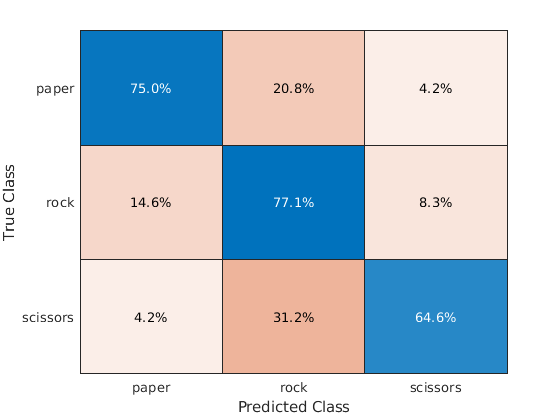

confusion_mat_norm3 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties


confusion_mat_norm3 = confusionchart(train_labels, validationPredictions3, 'Normalization','row-normalized')

save("trainedAlgorithms.mat", "trainedAlg1", "trainedAlg2", "trainedAlg3");